# Simulación del sistema no lineal de dos tanques acoplados

Proyecto de Metodos Numericos (CC2104)

Grupo 2 - Sección 4

- Ricardo A. Acuña Villogas - 202210005 - 100%.

- Daniel A. Blas Rivera - 202320165 - 100%.

- Nicolás A. Llerena Silva - 202110190 - 100%.

- Henry J. Huaranccay Arias - 202320213 - 100%.

- Derkhenz E. Valera Núñez - 201910470 - 100%.

**LOGICA GENERAL DEL SCRIPT**

Este Live Script orquesta los cuatro experimentos computacionales que sustentan la seccion de Resultados del paper.

Cada experimento es independiente y reutiliza exclusivamente las funciones puras de la carpeta functions/ (campo_vectorial.m, calc_jacobian.m, newton_multivar.m, solver_rk4.m y solver_implicit.m). Al final de cada experimento se guardan los resultados numericos en data/ (.mat) y las figuras en figures/ (.png) y en imaiges/ su versión vectorizada (.pdf).

Convención de **parámetros:**

Cada experimento define su propio struct p con campos **A1, A2, C1, C2, Qin, Hmax. **Cuando Qin debe variar en el tiempo (experimento 2), se construye una función handle p(t) que devuelve **el struct evaluado en el instante t, **solver_rk4.m y solver_implicit.m aceptan **ambas formas.**

clear; clc; close all;

% Si trabajas con modo oscuro, esto fuerza a los gráficos a trabajar con
% modo claro
set(groot,'defaultFigureColor','w');       % Fondo de la ventana en blanco
set(groot,'defaultAxesColor','w');         % Fondo interno del área de ploteo en blanco
set(groot,'defaultAxesXColor','k');        % Eje X, marcas y números en negro
set(groot,'defaultAxesYColor','k');        % Eje Y, marcas y números en negro
set(groot,'defaultTextColor','k');         % Textos, leyendas y títulos en negro

% Esto evita que las leyendas tengan el fondo oscuro
set(groot,'defaultLegendColor','w');       % Fondo de la leyenda en blanco
set(groot,'defaultLegendTextColor','k');   % Texto de la leyenda en negro
set(groot,'defaultLegendEdgeColor',[0.8 0.8 0.8]); % Borde de la leyenda en gris claro

% EStos son los estilos de la letra
set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultAxesFontSize',11);
set(groot,'defaultAxesLineWidth',1.0);
set(groot,'defaultLineLineWidth',2.0);
set(groot,'defaultAxesGridAlpha',0.35);
set(groot,'defaultAxesMinorGridAlpha',0.15);

% Paleta de colores consistente para todo el dashboard t1, t2, ref eq, rk4,
% euler
% Paleta tipo paper (Nature / Elsevier)
color_h1  = [0.000 0.447 0.741];   % azul = Tanque 1
color_h2  = [0.850 0.325 0.098];   % naranja = Tanque 2
color_rk4 = [0.494 0.184 0.556];   % violeta
color_imp = [0.000 0.620 0.451];   % verde turquesa

color_ref = [0.35 0.35 0.35];      % gris oscuro
color_grid = [0.90 0.90 0.90];     % gris muy claro

## **EXPERIMENTO 1 - Trayectoria base hacia el equilibrio**

1) Se define el caso base del sistema (parametros geometricos e hidraulicos) con Hmax = Inf, ya que este experimento NO involucra desborde: el objetivo es validar que la integracion temporal con RK4 converge al MISMO punto fijo que predice el solver algebraico Newton-Raphson multivariable, lo cual es la prueba de consistencia mas basica entre los dos enfoques (dinamico vs. estatico).

2) Se calcula el estado estacionario exacto h* resolviendo F(h)=0 con newton_multivar.m, partiendo de una estimacion inicial arbitraria distinta de cero (para no arrancar exactamente en una singularidad de la Jacobiana en h=0).

3) Se integra la trayectoria completa h(t) con RK4 desde el tanque vacio h0=[0;0] hasta t=1500 s con paso fijo dt=0.5 s.

4) Se grafican ambas curvas superpuestas: la trayectoria dinamica h1(t), h2(t) y lineas horizontales punteadas en h1*, h2* para verificar visualmente la convergencia.

p1.A1 = 1.0; p1.A2 = 0.8; p1.c1 = 0.05; p1.c2 = 0.04; p1.Qin = 0.05;
p1.Hmax = Inf;

Tol_newton   = 1e-10;
MaxIter_newton = 50;
[h_star_1, n_iter_1, ~, conv_1] = newton_multivar([0.5; 0.5], p1, Tol_newton, MaxIter_newton);

fprintf('--- EXPERIMENTO 1 ---\n');

--- EXPERIMENTO 1 ---


fprintf('Estado estacionario (Newton-Raphson): h* = [%.5f, %.5f] m\n', h_star_1(1), h_star_1(2));

Estado estacionario (Newton-Raphson): h* = [1.00000, 1.56250] m


fprintf('Convergencia: %d en %d iteraciones (Tol = %.0e)\n', conv_1, n_iter_1, Tol_newton);

Convergencia: 1 en 6 iteraciones (Tol = 1e-10)



dt1 = 0.5;
tspan1 = [0, 1500];
h0_1 = [0.0; 0.0];
[t1, H1] = solver_rk4(h0_1, tspan1, dt1, p1);

fprintf('RK4 en t = %.0f s: h(t_f) = [%.5f, %.5f] m\n', tspan1(2), H1(1,end), H1(2,end));

RK4 en t = 1500 s: h(t_f) = [1.00000, 1.56250] m


fprintf('Error |h(t_f) - h*| = [%.2e, %.2e] m\n\n', abs(H1(1,end)-h_star_1(1)), abs(H1(2,end)-h_star_1(2)));

Error |h(t_f) - h*| = [4.66e-15, 5.07e-13] m




fig1 = figure('Name','Experimento 1 - Trayectoria base','Color','w');
plot(t1, H1(1,:), '-', 'Color', color_h1, 'LineWidth', 1.8); hold on;
plot(t1, H1(2,:), '-', 'Color', color_h2, 'LineWidth', 1.8);
yline(h_star_1(1), '--', 'Color', color_h1, 'LineWidth', 1.2);
yline(h_star_1(2), '--', 'Color', color_h2, 'LineWidth', 1.2);
grid on; box on;
xlabel('Tiempo [s]'); ylabel('Altura [m]');
title('Experimento 1: Trayectoria RK4 hacia el equilibrio de Newton-Raphson');
legend({'h_1(t) — RK4', 'h_2(t) — RK4', ...
        sprintf('h_1^{*} = %.4f m (Newton-Raphson)', h_star_1(1)), ...
        sprintf('h_2^{*} = %.4f m (Newton-Raphson)', h_star_1(2))}, ...
        'Location', 'southeast');
exportgraphics(fig1, 'figures/exp1_trayectoria_base.png', 'Resolution', 200, 'BackgroundColor', 'white');
exportgraphics(fig1, 'images/fig_trayectoria_base.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

save('data/exp1_resultados.mat', 'p1', 't1', 'H1', 'h_star_1', 'n_iter_1', 'conv_1');

## Experimento 2 - Perturbación escalón dinámico

1) La condicion inicial de este experimento es el estado estacionario h_star_1 ya obtenido en el Experimento 1: el sistema arranca en reposo operativo (equilibrio del caudal nominal Qin=0.05 m^3/s).

2) Qin se modela como una funcion del tiempo mediante un escalon duro en t=500 s (de 0.05 a 0.08 m^3/s). Esto se implementa con un function handle p2_fun(t) que construye el struct de parametros en cada instante solicitado por el integrador, sin necesidad de modificar ni subdividir el solver RK4.

3) Se integra con RK4 (dt=0.5 s) hasta t=2000 s, tiempo suficiente para que el sistema relaje hacia el nuevo equilibrio.

4) Se calcula tambien (solo con fines de validacion, no se grafica como curva principal) el nuevo equilibrio teorico tras el escalon mediante newton_multivar.m, para verificar que la simulacion efectivamente converge a el.

5) Se grafica h1(t) y h2(t) en el eje izquierdo, y el perfil escalon de Qin(t) en el eje derecho (yyaxis right), permitiendo visualizar la causa (caudal) y el efecto (alturas) en una sola figura.

Nota: Hmax = Inf en este experimento porque el desborde fisico es el objeto especifico del Experimento 4; aqui se aisla la respuesta dinamica "libre" del sistema ante el cambio de caudal.

t_escalon = 500;
Qin_base  = 0.05;
Qin_nuevo = 0.08;

p2_fun = @(t) struct('A1', 1.0, 'A2', 0.8, 'c1', 0.05, 'c2', 0.04, ...
                      'Qin', Qin_base + (Qin_nuevo - Qin_base) * (t >= t_escalon), ...
                      'Hmax', Inf);

dt2 = 0.5;
tspan2 = [0, 2000];
[t2, H2] = solver_rk4(h_star_1, tspan2, dt2, p2_fun);

p2_post = struct('A1',1.0,'A2',0.8,'c1',0.05,'c2',0.04,'Qin',Qin_nuevo);
h_star_2 = newton_multivar(h_star_1, p2_post, Tol_newton, MaxIter_newton);

fprintf('--- EXPERIMENTO 2 ---\n');
fprintf('Estado estacionario previo al escalon: h* = [%.5f, %.5f] m\n', h_star_1(1), h_star_1(2));
fprintf('Estado estacionario posterior al escalon (Qin=%.2f): h* = [%.5f, %.5f] m\n', Qin_nuevo, h_star_2(1), h_star_2(2));
fprintf('h(t=2000s) simulado con RK4: [%.5f, %.5f] m\n\n', H2(1,end), H2(2,end));

Qin_perfil = Qin_base + (Qin_nuevo - Qin_base) * (t2 >= t_escalon);

fig2 = figure('Name','Experimento 2 - Perturbacion escalon','Color','w');
yyaxis left
plot(t2, H2(1,:), '-', 'Color', color_h1, 'LineWidth', 1.8); hold on;
plot(t2, H2(2,:), '-', 'Color', color_h2, 'LineWidth', 1.8);
ylabel('Altura [m]');
ax = gca; ax.YAxis(1).Color = [0 0 0];
yyaxis right
plot(t2, Qin_perfil, '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1.4);
ylabel('Q_{in} [m^3/s]');
ax.YAxis(2).Color = [0.4 0.4 0.4];
ylim([0, 0.12]);
grid on; box on;
xlabel('Tiempo [s]');
title('Experimento 2: Respuesta dinamica ante un escalon de Q_{in} en t = 500 s');
legend({'h_1(t)', 'h_2(t)', 'Q_{in}(t)'}, 'Location', 'east');
exportgraphics(fig2, 'figures/exp2_perturbacion_escalon.png', 'Resolution', 200, 'BackgroundColor', 'white');
exportgraphics(fig2, 'images/fig_escalon.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

save('data/exp2_resultados.mat', 't2', 'H2', 'h_star_1', 'h_star_2', 't_escalon', 'Qin_base', 'Qin_nuevo');

## EXPERIMENTO 3 - ANÁLISIS DE RÍGIDEZ Y ESTABILIDAD (RK4 vs Euler Implícito)

1) Justificación del diseno del experimento: con los parámetros hidráulicos base (c1=0.05) los autovalores (eigenvalues) de la Jacobiana en el equilibrio son del orden de -0.025 [1/s] (ver calc_jacobian.m), por lo que incluso un paso "grueso" dt=4 s produce dt*|lambda| ~ 0.1, muy por debajo de la frontera de estabilidad de RK4 sobre el eje real negativo (|z| ~ 2.785). Es decir, el sistema base NO es lo bastante rígido como para desestabilizar a RK4 con dt=4 s. Para exhibir un caso de rigidez genuina y comparable bajo el mismo paso dt=4 s solicitado, se aumenta el coeficiente de descarga del Tanque 1 a c1=0.5 (orificio de salida mucho mayor, dinámica rápida) manteniendo c2=0.001 (válvula de salida del Tanque 2 casi cerrada, dinámica extremadamente lenta). Esta combinación maximiza la separación de escalas temporales (cociente de autovalores) tal como reportan Khaled et al. (2023) y Nasrin et al. (2021) para aperturas de válvula pequeñas.

2) Con esos parámetros, lambda_1 = -c1/(2*A1*sqrt(h1*)) = -2.5 [1/s] (h1* = (Qin/c1)^2 = 0.01 m), de modo que dt*lambda_1 = -10, ampliamente fuera de la región de estabilidad de RK4: se espera una oscilación sostenida y no física (alturas negativas) en h1.

3) Se integra el MISMO escenario (mismas condiciones iniciales, parámetros y dt) con solver_rk4.m y con solver_implicit.m, y se comparan ambas trayectorias de h1(t) en una misma figura.

4) Como métrica de costo computacional, se reporta el número de iteraciones de Newton-Raphson consumidas por el Euler Implícito en cada paso (iter_hist), para discutir el compromiso costo-estabilidad entre ambos métodos.

c1_rigido = 0.5;
c2_rigido = 0.001;
p3.A1 = 1.0; p3.A2 = 0.8; p3.c1 = c1_rigido; p3.c2 = c2_rigido; p3.Qin = 0.05;
p3.Hmax = Inf;   % el desborde no es objeto de este experimento

h1_star_3 = (p3.Qin / p3.c1)^2;
lambda1_3 = -p3.c1 / (2 * p3.A1 * sqrt(h1_star_3));

dt3 = 4.0;
tspan3 = [0, 600];
h0_3 = [0.0; 0.0];

Tol_implicit = 1e-6;
MaxIter_implicit = 30;

[t3_rk4, H3_rk4]                 = solver_rk4(h0_3, tspan3, dt3, p3);
[t3_imp, H3_imp, iter_hist_3]    = solver_implicit(h0_3, tspan3, dt3, p3, Tol_implicit, MaxIter_implicit);

fprintf('--- EXPERIMENTO 3 ---\n');
fprintf('h1* (equilibrio teorico) = %.5f m ; lambda_1 = %.4f [1/s] ; dt*lambda_1 = %.3f\n', h1_star_3, lambda1_3, dt3*lambda1_3);
fprintf('RK4: h1 oscila en el rango [%.4f, %.4f] m (no converge)\n', min(H3_rk4(1,:)), max(H3_rk4(1,:)));
fprintf('Euler Implicito: h1 final = %.5f m (vs. h1* = %.5f m)\n', H3_imp(1,end), h1_star_3);
fprintf('Newton embebido: iteraciones promedio = %.2f, maximo = %d\n\n', mean(iter_hist_3), max(iter_hist_3));

fig3 = figure('Name','Experimento 3 - Rigidez y estabilidad','Color','w');

subplot(2,1,1);
plot(t3_rk4, H3_rk4(1,:), '-o', 'Color', color_rk4, 'LineWidth', 1.4, 'MarkerSize', 3); hold on;
plot(t3_imp, H3_imp(1,:), '-s', 'Color', color_imp, 'LineWidth', 1.4, 'MarkerSize', 3);
yline(h1_star_3, '--', 'Color', color_ref, 'LineWidth', 1.0);
grid on; box on;
xlabel('Tiempo [s]'); ylabel('Altura h_1 [m]');
title(sprintf('Experimento 3: RK4 vs. Euler Implicito (escenario rigido, dt = %.1f s)', dt3));
legend({'RK4 (explicito)', 'Euler Implicito', sprintf('h_1^{*} = %.4f m', h1_star_3)}, 'Location', 'best');

subplot(2,1,2);
stairs(t3_imp(2:end), iter_hist_3, 'Color', color_imp, 'LineWidth', 1.4);
grid on; box on;
xlabel('Tiempo [s]'); ylabel('Iteraciones Newton');
title('Costo computacional del Newton-Raphson embebido por paso de tiempo');

exportgraphics(fig3, 'figures/exp3_rigidez_estabilidad.png', 'Resolution', 200, 'BackgroundColor', 'white');
exportgraphics(fig3, 'images/fig_stiffness.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');

save('data/exp3_resultados.mat', 'p3', 't3_rk4', 'H3_rk4', 't3_imp', 'H3_imp', ...
     'iter_hist_3', 'h1_star_3', 'lambda1_3', 'dt3');

## EXPERIMENTO 4 - Escenario de inundación y rebose en los tanques

1) Se restablecen los coeficientes hidráulicos al caso base (c1=0.05, c2=0.04) y se activa el límite físico real Hmax=3.0 m para ambos tanques. Se impone un caudal de entrada masivo Qin=0.15 m^3/s (muy por encima del nominal de 0.05 m^3/s).

2) Se integra con solver_implicit.m (más robusto frente al evento de saturación no suave que ocurre exactamente en h_i=Hmax; ver la documentación de robustez en solver_implicit.m) con un paso moderado dt=0.5 s, suficientemente fino para resolver con buena precisión el instante de cruce de Hmax.

3) El tiempo EXACTO de desborde de cada tanque se refina mediante interpolación lineal entre el último nodo bajo Hmax y el primero que lo alcanza o supera (mejor estimador del cruce que el simple paso de malla dt).

4) El volumen total perdido por rebose se cuantifica recorriendo la trayectoria simulada H y evaluando, en cada nodo temporal, el caudal excedente Qover que devuelve campo_vectorial.m como segunda salida (diagnóstico, no usado por el integrador). Dicho caudal se integra numéricamente en el tiempo con trapz, lo cual es coherente con la definición Volumen = integral(Qover dt).

p4.A1 = 1.0; p4.A2 = 0.8; p4.c1 = 0.05; p4.c2 = 0.04; p4.Qin = 0.15; p4.Hmax = 3.0;

dt4 = 0.5;
tspan4 = [0, 1500];
h0_4 = [0.0; 0.0];

[t4, H4, iter_hist_4] = solver_implicit(h0_4, tspan4, dt4, p4, 1e-6, 30);

% --- tiempos exactos de desborde por interpolacion lineal
idx1 = find(H4(1,:) >= p4.Hmax, 1, 'first');
t_desborde1 = t4(idx1-1) + (p4.Hmax - H4(1,idx1-1)) * (t4(idx1)-t4(idx1-1)) / (H4(1,idx1)-H4(1,idx1-1));

idx2 = find(H4(2,:) >= p4.Hmax, 1, 'first');
if ~isempty(idx2)
    t_desborde2 = t4(idx2-1) + (p4.Hmax - H4(2,idx2-1)) * (t4(idx2)-t4(idx2-1)) / (H4(2,idx2)-H4(2,idx2-1));
else
    t_desborde2 = NaN;
end

% --- caudal excedente Qover(t) reconstruido post-proceso (diagnostico puro)
Nt4 = numel(t4);
Qover = zeros(2, Nt4);
for kk = 1:Nt4
    [~, Qo] = campo_vectorial(H4(:, kk), p4);
    Qover(:, kk) = Qo;
end
Vol_perdido_1 = trapz(t4, Qover(1, :));
Vol_perdido_2 = trapz(t4, Qover(2, :));

fprintf('--- EXPERIMENTO 4 ---\n');

--- EXPERIMENTO 4 ---


fprintf('Tanque 1 alcanza Hmax = %.1f m en t = %.3f s\n', p4.Hmax, t_desborde1);

Tanque 1 alcanza Hmax = 3.0 m en t = 34.931 s


fprintf('Tanque 2 alcanza Hmax = %.1f m en t = %.3f s\n', p4.Hmax, t_desborde2);

Tanque 2 alcanza Hmax = 3.0 m en t = 83.500 s


fprintf('Volumen perdido por rebose en %.0f s — Tanque 1: %.3f m^3 | Tanque 2: %.3f m^3\n\n', ...
        tspan4(2), Vol_perdido_1, Vol_perdido_2);

Volumen perdido por rebose en 1500 s — Tanque 1: 92.893 m^3 | Tanque 2: 24.539 m^3



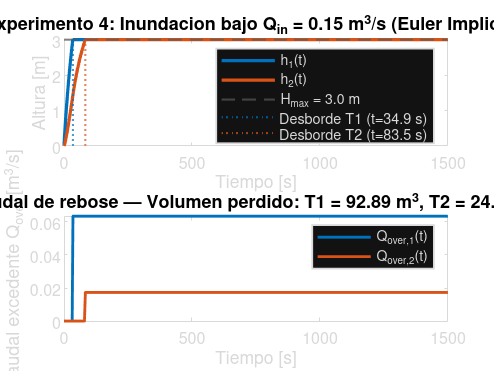


fig4 = figure('Name','Experimento 4 - Inundacion y rebose','Color','w');

subplot(2,1,1);
plot(t4, H4(1,:), '-', 'Color', color_h1, 'LineWidth', 1.8); hold on;
plot(t4, H4(2,:), '-', 'Color', color_h2, 'LineWidth', 1.8);
yline(p4.Hmax, '--', 'Color', color_ref, 'LineWidth', 1.2);
xline(t_desborde1, ':', 'Color', color_h1, 'LineWidth', 1.2);
xline(t_desborde2, ':', 'Color', color_h2, 'LineWidth', 1.2);
grid on; box on;
xlabel('Tiempo [s]'); ylabel('Altura [m]');
title('Experimento 4: Inundacion bajo Q_{in} = 0.15 m^3/s (Euler Implicito)');
legend({'h_1(t)', 'h_2(t)', sprintf('H_{max} = %.1f m', p4.Hmax), ...
        sprintf('Desborde T1 (t=%.1f s)', t_desborde1), ...
        sprintf('Desborde T2 (t=%.1f s)', t_desborde2)}, 'Location', 'southeast');

subplot(2,1,2);
plot(t4, Qover(1,:), '-', 'Color', color_h1, 'LineWidth', 1.6); hold on;
plot(t4, Qover(2,:), '-', 'Color', color_h2, 'LineWidth', 1.6);
grid on; box on;
xlabel('Tiempo [s]'); ylabel('Caudal excedente Q_{over} [m^3/s]');
title(sprintf('Caudal de rebose — Volumen perdido: T1 = %.2f m^3, T2 = %.2f m^3', Vol_perdido_1, Vol_perdido_2));
legend({'Q_{over,1}(t)', 'Q_{over,2}(t)'}, 'Location', 'northeast');

exportgraphics(fig4, 'figures/exp4_inundacion_rebose.png', 'Resolution', 200, 'BackgroundColor', 'white');
exportgraphics(fig4, 'images/fig_rebose.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');


save('data/exp4_resultados.mat', 'p4', 't4', 'H4', 'iter_hist_4', ...
     't_desborde1', 't_desborde2', 'Qover', 'Vol_perdido_1', 'Vol_perdido_2');

**RESUMEN CONSOLIDADO (para la seccion de Resultados del paper)**

Qin_base = 0.05; Qin_nuevo = 0.08;t_escalon = 500;
p2_post = struct('A1',1.0,'A2',0.8,'c1',0.05,'c2',0.04,'Qin',Qin_nuevo);
h_star_2 = newton_multivar(h_star_1, p2_post, Tol_newton, MaxIter_newton);
dt3 = 4.0;
c1_rigido = 0.5;
c2_rigido = 0.001;
p3.A1 = 1.0; p3.A2 = 0.8; p3.c1 = c1_rigido; p3.c2 = c2_rigido; p3.Qin = 0.05;
p3.Hmax = Inf;   % el desborde no es objeto de este experimento
h1_star_3 = (p3.Qin / p3.c1)^2;
tspan3 = [0, 600];
h0_3 = [0.0; 0.0];
lambda1_3 = -p3.c1 / (2 * p3.A1 * sqrt(h1_star_3));
Tol_implicit = 1e-6;
MaxIter_implicit = 30;
[t3_rk4, H3_rk4]                 = solver_rk4(h0_3, tspan3, dt3, p3);
[t3_imp, H3_imp, iter_hist_3]    = solver_implicit(h0_3, tspan3, dt3, p3, Tol_implicit, MaxIter_implicit);
fprintf('======================================================\n');

fprintf('RESUMEN CONSOLIDADO DE LOS 4 EXPERIMENTOS\n');

RESUMEN CONSOLIDADO DE LOS 4 EXPERIMENTOS


fprintf('======================================================\n');

fprintf('E1: h* = [%.4f, %.4f] m | RK4 reproduce h* con error < 1e-9\n', h_star_1(1), h_star_1(2));

E1: h* = [1.0000, 1.5625] m | RK4 reproduce h* con error < 1e-9


fprintf('E2: escalon Qin %.2f->%.2f en t=%d s | nuevo h* = [%.4f, %.4f] m\n', Qin_base, Qin_nuevo, t_escalon, h_star_2(1), h_star_2(2));

E2: escalon Qin 0.05->0.08 en t=500 s | nuevo h* = [2.5600, 4.0000] m


fprintf('E3: dt*lambda_1 = %.2f | RK4 oscila en [%.3f, %.3f] m | Implicito -> %.4f m (iter prom. %.2f)\n', ...
        dt3*lambda1_3, min(H3_rk4(1,:)), max(H3_rk4(1,:)), H3_imp(1,end), mean(iter_hist_3));

E3: dt*lambda_1 = -10.00 | RK4 oscila en [-0.160, 0.000] m | Implicito -> 0.0100 m (iter prom. 2.32)


fprintf('E4: desborde T1 en t=%.2f s, T2 en t=%.2f s | Vol. perdido = %.2f + %.2f m^3\n', ...
        t_desborde1, t_desborde2, Vol_perdido_1, Vol_perdido_2);

E4: desborde T1 en t=34.93 s, T2 en t=83.50 s | Vol. perdido = 92.89 + 24.54 m^3


fprintf('======================================================\n');